## 1.Neodređeni integrali

### 1.1 Matematička osnova

Neka je funkcija $f$ definisana na intervalu $(a, b)$. Ako postoji funkcija $F$ takva da važi $F'(x)=f(x), \; \forall x \in (a, b)$, onda kažemo da je $F$ **primitivna funkcija** funkcije $f$ na intervalu $(a, b)$.

Skup svih primitivnih funkcija funkcije $f(x)$ zovemo **neodređenim integralom** funkcije $f(x)$ i označavamo sa  $\int{f(x)}\,dx$. 

Ako je $F(x)$ jedna primitivna funkcija funkcije $f(x)$ na intervalu $(a, b)$, onda skup $\int{f(x)}\,dx$ za $x \in (a, b)$ pišemo kao:


$$\int{f(x)}\,dx = F(x) + C, \quad C \in \mathbb{R}, \; x \in (a, b)$$


### 1.2 Rešavanje zadataka

Za rešavanje neodređenih integrala koristićemo int funkciju a za crtanje grafika plot ili fplot.

#### Zadatak 1. - Jednostavan integral

Naći rešenje integrala:


$$\int{x^2}\,dx$$


Definišemo promenljive i funkciju:

syms f(x);
f(x) = x^2

$$f(x) = x^{2}$$

Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f,x)

$$F(x) = \frac{x^{3}}{3}$$

Tako nalazimo da je rešenje integrala:


$$\int{x^2}\,dx = \frac{x^3}{3} + C$$


Rešenje možemo skicirati:

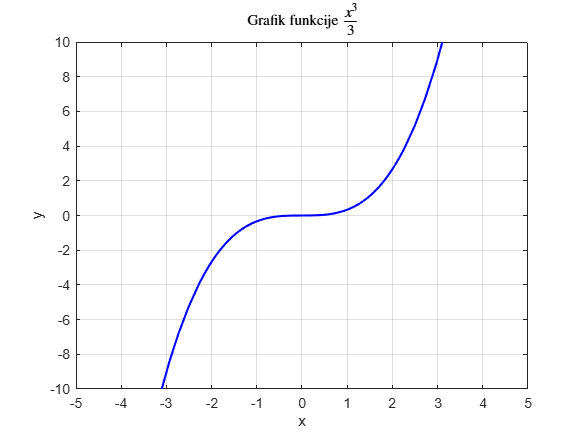

fplot(F, [-5, 5], 'b', 'LineWidth', 1.5); 

% Ograničenja po osama
xlim([-5 5]); 
ylim([-10 10]); 

xlabel('x'); 
ylabel('y'); 
title('Grafik funkcije $\frac{x^3}{3}$', 'Interpreter', 'latex');
grid on; 

### Zadatak 2. - Dvojni integral

Naći rešenje dvojnog integrala:


$$\int\int{(xy)}\,dx \,dy
$$


Definišemo promenljive i funkciju:

syms f(x,y);
f(x,y) = x*y

$$f(x, y) = x\,y$$

Koristimo proceduru ***int ***2 puta kako bismo dobili rešenje:

F = int(int(f,x),y)

$$F(x, y) = \frac{x^{2}\,y^{2}}{4}$$

#### Zadatak 3. - Trojni integral i trigonometrijska funkcija

Naći rešenje trojnog integrala:


$$\int\int\int{(\sin{x}yz^2)}\,dx \,dy \,dz$$


Definišemo promenljive i funkciju:

syms f(x,y,z);
f(x,y,z) = sin(x)*y*z^2

$$f(x, y, z) = y\,z^{2}\,\sin\left(x\right)$$

Koristimo proceduru ***int ****3* puta kako bismo dobili rešenje:

F = int(int(int(f,x),y),z)

$$F(x, y, z) = -\frac{y^{2}\,z^{3}\,\cos\left(x\right)}{6}$$

#### Zadatak 4. - Integral iracionalne funkcije


$$\int{\frac{-x}{\sqrt{1-x^2}}}\,dx$$


Definišemo promenljive i funkciju pa određujemo integral:

syms f(x);
f(x) = -x/(sqrt(1-x^2))

$$f(x) = -\frac{x}{\sqrt{1-x^{2}}}$$

F = int(f,x)

$$F(x) = \sqrt{1-x^{2}}$$

Rešenje možemo skicirati:

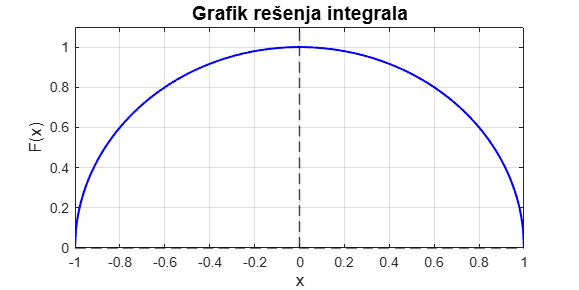


fja = @(x) sqrt(1-x.^2); 

% Generisanje x vrednosti pa računamo y preko x
n = 500;  
x_vals = linspace(-1, 1, n); 
y_vals = fja(x_vals); 


plot(x_vals, y_vals, 'b', 'LineWidth', 1.5); 
title('Grafik rešenja integrala', 'FontSize', 14);
xlabel('x', 'FontSize', 12); 
ylabel('F(x)', 'FontSize', 12); 

% Dodavanje isprekidane linije na osama
xline(0, '--k', 'LineWidth', 1); 
yline(0, '--k', 'LineWidth', 1); 

%Proširenje za y da bi lepo videlo na grafiku
ylim([0, 1.1])

grid on;
% Dimenzije figure
set(gcf, 'Position', [100, 100, 800, 400]); 

#### Zadatak 5. - Integral sa parametrom


$$\int{x^a\ln{x}}\,dx$$
    

Definišemo promenljive, parametar i funkciju pa određujemo integral:

syms f(x);
syms a;
f(x) = x^a*log(x)

$$f(x) = x^{a}\,\log\left(x\right)$$

F = int(f,x)

$$F(x) = \left\{ \begin{array}{cl} \frac{{\log\left(x\right)}^{2}}{2} & \text{ if }a=-1\\ \frac{x^{a+1}\,\left(\log\left(x\right)\,\left(a+1\right)-1\right)}{{\left(a+1\right)}^{2}} & \text{ if }a\neq -1 \end{array}\right.$$

## 2. Određeni integrali

### **2.1 Matematička osnova**

Neka je $[a,b] \subseteq \mathbb{R}$ neki interval. Podelimo taj interval pomoću tačaka  $a = x_0 < x_1 < x_2 < \ldots < x_n = b,$ a zatim u svakom od podintervala $[x_i, x_{i+1}]$, $i=0, \ldots, n-1$, izaberimo po jednu tačku i označimo je sa $\xi_i$.  

Tačke $x_i$ i $\xi_i$ definišu podelu intervala $[a,b]$, u oznaci: $d = (x_0, x_1, \ldots, x_n; \xi_0, \xi_1, \ldots, \xi_{n-1})$.

Neka je data funkcija $f: [a,b] \to \mathbb{R}$. Integralna suma funkcije $f$ na intervalu $[a,b]$ pri podeli $d$ se definiše kao $S(f, d, a, b) = \sum_{i=0}^{n-1} f(\xi_i) (x_{i+1} - x_i)$.

$S(f,d,a,b)$ = zbir površina pravougaonika čije su osnove segmenti $[x_i,x_{i+1}]$ (dakle dužina $x_{i+1} - x_i$), a visine $f(\xi_i)$.

Norma podele $d= (x_0, \ldots, x_n; \xi_i, \ldots, \xi_{n-1})$ , u oznaci $||d||$, predstavlja dužinu najvećeg od podintervala date podele:  $||d|| = \max_{0 \leq i \leq n -1}(x_{i+1} - x_i)$

Ako postoji konačna granična vrednost $I = \lim_{\|d\| \to 0} S(f, d, a, b)$

i ako ona ne zavisi od podele $d$ intervala $[a,b]$, onda se realan broj $I$ naziva određenim (ili Rimanovim) integralom funkcije $f$ na intervalu $[a,b]$ i označava se sa:

$I = \int_a^b f(x) dx$.

### **2.1 Rešavanje zadataka**

#### Zadatak 1. - Nalaženje integrala pomoću integralnih suma

Naći rešenje integrala:


$$\int_{-1}^{1}{\sqrt{1-x^2}\,dx}$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f(x) = sqrt(sym(1)-x^2)

$$f(x) = \sqrt{1-x^{2}}$$

Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f(x) = sqrt(sym(1)-x^2)

$$f(x) = \sqrt{1-x^{2}}$$

Znamo da je ovo jednačina polukružnice, pa pošto je integral po ovoj jednačini sa ovim granicama ustvari površina polukruga poluprečnika 1. Možemo očekivati da rezultat bude: $\frac{\pi}{2}$

Probaćemo da odredimo ovu površinu bez procedura za integraciju, već aproksimacijom i integralnim sumama.

Interval $[-1, 1]$ ćemo podeliti na ekvidistantne razmake. Razmak između 2 odbirka će biti jedna stranica pravougaonika $(x_{i+1} - x_i)$, a druga će biti vrednost $f(x_i)$.

Sumiranjem površina ovih pravougaonika ćemo dobiti površinu polukruga.

Rešenje možemo skicirati:


f_lambdified = matlabFunction(f);


x_vals = linspace(-1, 1, 48); % 48 odbiraka pošto je 50 max za grafik
y_vals = f_lambdified(x_vals); 

povrsina = 0;

plot(x_vals, y_vals, 'r-', 'LineWidth', 1.5, 'DisplayName', 'Polukrug');

%mora da se čeka da bi mogli da nacrtamo više objekata na jednom grafiku
hold on;

% Podešavanje odnosa stranica
set(gca, 'DataAspectRatio', [1 1 1]); 
plot([0, 0], [-0.1, 1.1], 'k-', 'LineWidth', 0.8, 'HandleVisibility', 'off'); % 'HandleVisibility', 'off' - da se ne vidi data1 na legendi
plot([-1.1, 1.1], [0, 0], 'k-', 'LineWidth', 0.8, 'HandleVisibility', 'off'); 

% Podešavanje granica osi
xlim([-1.1, 1.1]);
ylim([0, 1.1]);
grid on;

% Dodavanje pravougaonika za aproksimaciju površine
for i = 1:(length(x_vals)-1)
    dx = x_vals(i+1) - x_vals(i); % Širina pravougaonika
    y = f_lambdified(x_vals(i+1)); % Visina pravougaonika

    % Popunjavanje pravougaonika bojom
    if i == 1 % [x][y] matrice temena pravougaonika
        fill([x_vals(i), x_vals(i), x_vals(i+1), x_vals(i+1)], [0, y, y, 0], 'b', 'FaceAlpha', 0.5, 'DisplayName', 'Pravougaonik');
    else
        fill([x_vals(i), x_vals(i), x_vals(i+1), x_vals(i+1)], [0, y, y, 0], 'b', 'FaceAlpha', 0.5, 'HandleVisibility', 'off');
    end

    % Računanje površine pravougaonika
    p = dx * y;
    povrsina = povrsina + p;
end
fprintf('Aproksimirana površina: %.4f\n', povrsina);

Aproksimirana površina: 1.5656


fprintf('Prava površina: %.4f\n', double(pi/2));

Prava površina: 1.5708


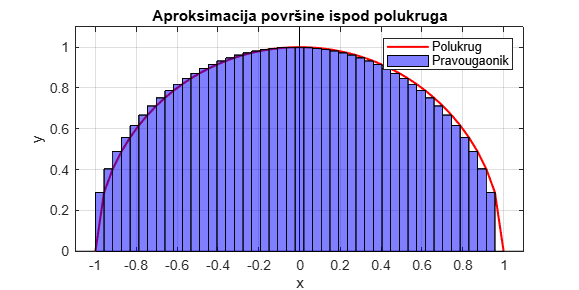

legend();
title('Aproksimacija površine ispod polukruga');
xlabel('x');
ylabel('y');
%Završava sa čekanjem i dobijamo grafik
hold off;

**Prikaz animacije:**

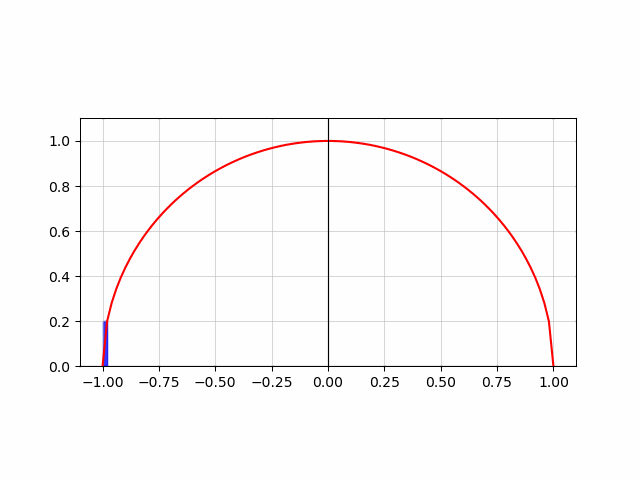

**Ovu animaciju i kod koji je generiše možete naći u priloženim fajlovima.**

#### Zadatak 2. - Simboličko i numeričko izračunavanje integrala pomoću trapezne i Simpsonove formule

Naći rešenje integrala:


$$\int_{2}^{3}{x^2}\,dx$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f(x) = x^2

$$f(x) = x^{2}$$

`Umesto "pešaka" da računamo integral, kao u prvom zadatku, koristimo proceduru ``int`` iz kako bismo dobili rešenje:`

F = int(f, 2, 3)

$$F = \frac{19}{3}$$

F_tacno = vpa(F)

$$F\_tacno = 6.3333333333333333333333333333333$$

U Matlabu postoje numeričke metode za izračunavanje integrala:

**Numerička integracija pomoću izraza**

**Numerička integracija pomoću vrednosti**

U Matlabu moguće je vršiti **numeričko** izračunavanje integrala, funkcijom ***integral ***koja vrši adaptivnu numeričku integraciju. Ova funkcija prima podintegralnu funkciju koja je definisana kao anonimna.

f = @(t)t.^2;
F_adaptivno = vpa(integral(f, 2, 3))

$$F\_adaptivno = 6.3333333333333333333333333333333$$

Koristićemo i **trapeznu** i **kvadraturnu** formulu:

f = @(x)x.^2;                  % Definišemo funkciju 
x_vals = linspace(2, 3, 100);  % Vektor sa 100 tačaka u opsegu [2, 3]
y_vals = f(x_vals);            % Vrednosti funkcije f(x) na tačkama x

val_trap = vpa(trapz(x_vals, y_vals))

$$val\_trap = 6.333350338400843604347301152302$$

val_quad = vpa(quadgk(f, 2, 3))

$$val\_quad = 6.3333333333333333333333333333333$$

**Apsolutna greška adaptivne metode**

abs(F_tacno-F_adaptivno)

$$ans = 0.0$$

**Apsolutna greška kvadraturne metode**

abs(F_tacno-val_quad)

$$ans = 0.0$$

**Apsolutna greška trapezne metode**

abs(F_tacno-val_trap)

$$ans = 0.00001700506751027101396781896861891$$

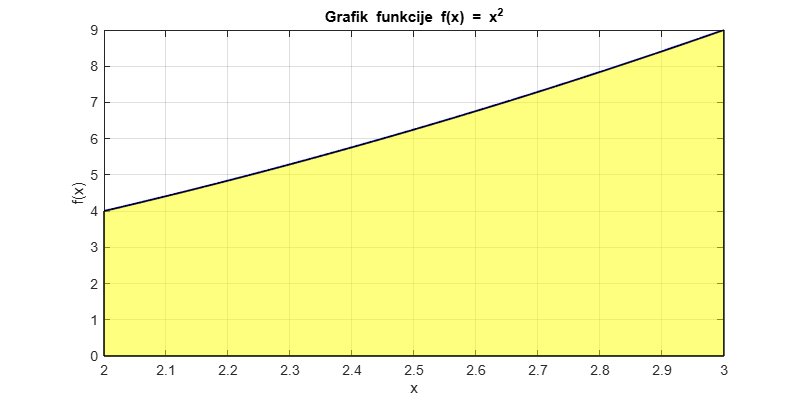

plot(x_vals, y_vals, 'b', 'LineWidth', 1.5); 
hold on;

fill([x_vals, fliplr(x_vals)], [zeros(size(x_vals)), fliplr(y_vals)], 'y', 'FaceAlpha', 0.5); 

title('Grafik funkcije f(x) = x^2');
xlabel('x');
ylabel('f(x)');
grid on;
hold off;

#### Zadatak 3. - Integral funkcije koja je definisana drugačije u različitim intervalima

Ako je f-ja f definisana sa: $$$ f(x) = \begin{cases} 
1 - x, & 0 \leq x \leq 1 \\  x^2, & 1 < x \leq 2 
 \end{cases} $$$ , izračunati:    


$$\int_{0}^{2}{f(x)}\,dx$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f(x) = piecewise(0 <= x & x <= 1, 1 - x, 1 < x & x <= 2, x^2)

$$f(x) = \left\{ \begin{array}{cl} 1-x & \text{ if }x\in \left[0,1\right]\\ x^{2} & \text{ if }x\in \left(1,2\right] \end{array}\right.$$

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f, x, 0, 2)

$$F = \frac{17}{6}$$

#### Zadatak 4. -  Integral inverzne trigonometrijske funkcije; Trapezna metoda ručno i preko procedure

Naći rešenje integrala:


$$\int_{2}^{3}{\arcsin (\sqrt{\frac{x}{x+1}})}\,dx$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f(x) = asin(sqrt(x/(x+sym(1))))

$$f(x) = \mathrm{asin}\left(\sqrt{\frac{x}{x+1}}\right)$$

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f, x, 2, 3), eval(F), F_tacno = vpa(F)

$$F = \frac{4\,\pi }{3}-2\,\mathrm{asin}\left(\frac{\sqrt{6}}{3}\right)-\mathrm{atan}\left(\sqrt{2}\right)+\sqrt{2}-\sqrt{3}$$

ans = 1.0050

$$F\_tacno = 1.0050031052170809053995289195292$$

Sada ćemo iskoristiti **kompozitnu trapeznu** formulu:


$$T(h) = \frac{h}{2}(f(a) + f(b) + 2\sum_{i=1}^{m-1}{f_i})$$


Gde je $h$ korak za tabeliranje funkcije.

Tabeliraćemo funkciju na 100 000 ekvidistantnih tačaka:

n = 100000;
a = 2;
b = 3;
h = (b-a)/n;
f = @(x)asin(sqrt(x./(x+1)));
x_vals = linspace(a, b, n);
y_vals = f(x_vals) ;
h

h = 1.0000e-05

Primenićemo formulu:

F_trapz_procenjeno = vpa((h/2)*(f(a) + f(b) + 2*sum(y_vals(1:n-1))))

$$F\_trapz\_procenjeno = 1.0050026083518293074092753158766$$

A sad ćemo iskoristiti ugrađenu proceduru:

F_trapz = vpa(trapz(x_vals, y_vals))

$$F\_trapz = 1.0050031052167001099917342799017$$

**Apsolutna greška naše procene **

abs(F_trapz_procenjeno - F_tacno)

$$ans = 0.00000049686525159799025360365263846109$$

**Apsolutna greška procedure:**

abs(F_trapz - F_tacno)

$$ans = 0.00000000000038079540779463962750237772116997$$

**Razlika između naše procene i ugrađene procedure**

abs(F_trapz - F_trapz_procenjeno)

$$ans = 0.00000049686487080258245896402513608336$$

#### Zadatak 5. - Integral kombinacija logaritma i trigonometrije; Numeričko izračunavanje 

Naći rešenje integrala:


$$\int_{-1/2}^{1/2}{ \cos x \ln \frac{1+x}{1-x}}\,dx$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f = cos(x)*log((x+sym(1))/(sym(1)-x))

$$f = \log\left(-\frac{x+1}{x-1}\right)\,\cos\left(x\right)$$

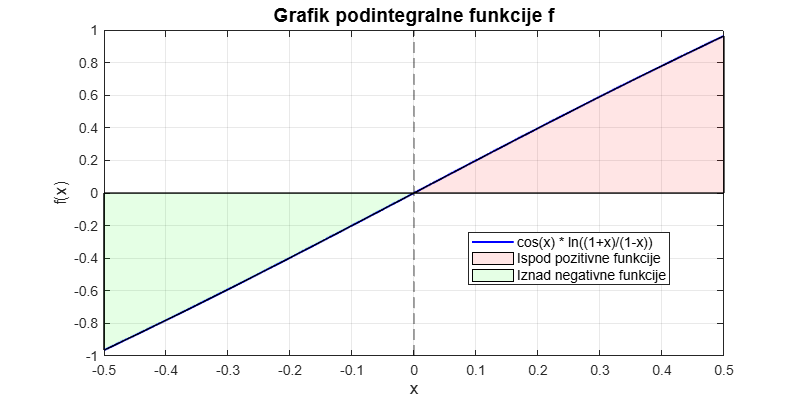

x_vals = linspace(-0.5, 0.5, 500);
f_handle = matlabFunction(f);
y_vals = f_handle(x_vals);

plot(x_vals, y_vals, 'DisplayName', 'cos(x) * ln((1+x)/(1-x))', 'Color', 'blue', 'LineWidth', 1.5); 

hold on;
% Popunjavanje ispod pozitivnih delova funkcije
fill([x_vals, fliplr(x_vals)], [zeros(size(x_vals)), fliplr(y_vals .* (y_vals > 0))], ...
    'r', 'FaceAlpha', 0.1, 'DisplayName', 'Ispod pozitivne funkcije');

% Popunjavanje iznad negativnih delova funkcije
fill([x_vals, fliplr(x_vals)], [zeros(size(x_vals)), fliplr(y_vals .* (y_vals < 0))], ...
    'g', 'FaceAlpha', 0.1, 'DisplayName', 'Iznad negativne funkcije');


title('Grafik podintegralne funkcije f', 'FontSize', 14);
% Nazivi osi
xlabel('x', 'FontSize', 12);
ylabel('f(x)', 'FontSize', 12);
% Dodavanje osi
yline(0, 'Color', 'black', 'LineWidth', 0.8, 'HandleVisibility', 'off'); % x osa je puna linija
xline(0, 'Color', 'black', 'LineWidth', 0.8, 'LineStyle', '--',  'HandleVisibility', 'off'); % y osa je isprekidana linija
% Dodavanje legende
legend('FontSize', 10, 'Location', 'best');
% Prikaz mreže
grid on;
set(gca, 'GridAlpha', 0.1); % Prozirnost mreže
% Prikaz figure
hold off;

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f, x, -0.5, 0.5)

$$F = \int_{-\frac{1}{2}}^{\frac{1}{2}}\log\left(-\frac{x+1}{x-1}\right)\,\cos\left(x\right)\mathrm{d}x$$

Pošto Matlab ne zna simbolički da reši integral, probaćemo **numerički**:

integral(f_handle, -0.5, 0.5)

ans = 2.0817e-17

Znači, vrednost integrala je 0. Što se i očekivalo sa grafika podintegralne funkcije.

Možemo da probamo i preko **trapezne formule**:

x_vals = linspace(-0.5, 0.5, 500);
y_vals = f_handle(x_vals);

trapz(x_vals, y_vals)

ans = 5.9631e-19

#### Zadatak 6. - Nesvojstveni integral gde interval integracije nije konačan; Simboličko i numeričko rešenje pomoću kvadraturne formule

Naći rešenje integrala:


$$\int_{1}^{\infty }{\frac{dx}{x(x+1)}}\,$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f = sym(1)/(x*(sym(1)+x))

$$f = \frac{1}{x\,\left(x+1\right)}$$

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f, x, 1, inf)

$$F = \log\left(2\right)$$

Sada ćemo odraditi i **numeričko** rešenje: definišemo funkciju pa koristeći **kvadraturnu** formulu dolazimo do rešenja:

f_handle = matlabFunction(f);
F_quad = vpa(quadgk(f_handle, 1, inf))

$$F\_quad = 0.69314718055994528622676398299518$$

**Apsolutna greška kvadraturne metode**

abs(vpa(F)-F_quad)

$$ans = 0.000000000000000023190468138462996154948543730496$$

#### Zadatak 7. - Nesvojstveni integral gde podintegralna funkcija nije ograničena na datom intervalu

Naći rešenje integrala:


$$\int_{0}^{1}{\frac{dx}{\sqrt{x}}}\,$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f = sym(1)/sqrt(x)

$$f = \frac{1}{\sqrt{x}}$$

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f, x, 0, 1)

$$F = 2$$

### 2.3 Primena integrala Zadaci

#### Zadatak 1. - Površina ravne figure

Izračunati veličinu površine koja ograničava kriva $y= \ln x$ i prave $x = \frac{1}{2}$ i $x=2$.

Formula koja se koristi za računanje površine ravne figure je: $P = \int _{a}^{b}(f(x)-g(x))\,dx$.

Ako je situacija da y osa razdvaja dve površine onda se koristi: $P = P_1 + P_2 = \int _{a}^{c}(f(x)-0)\,dx + \int _{c}^{b}(0-f(x))\,dx$ pri čemu je deo od $a$ do $c$ pozitivan, a deo od $c$ do $b$ negativan.

Takođe se ovo  može zapisati pomoću apsolutne vrednosti: $P = \int _{a}^{b} |f(x)| \,dx$

Na osnovu grafika vidimo da se površina deli na 2 dela i da u tački $(0,1)$ se menja pa integral delimo na 2 dela:


$$P = P_1 + P_2 = \int _{\frac{1}{2}}^{1}(0-lnx)\,dx + \int _{1}^{2}(lnx-0)\,dx = -\int _{\frac{1}{2}}^{1}lnx\,dx + \int _{1}^{2}lnx\,dx$$


Definisaćemo promenljive i podintegralnu funkciju:

syms f(x);
f(x) = log(x)

$$f(x) = \log\left(x\right)$$

Grafik:

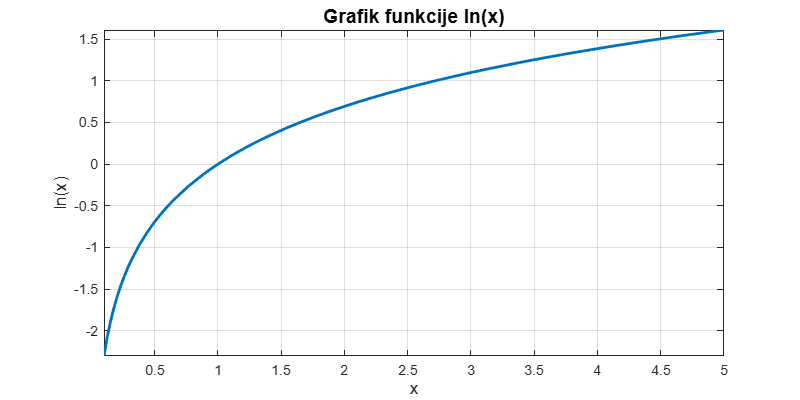

fplot(f, [0.1, 5], 'LineWidth', 2)
title('Grafik funkcije ln(x)', 'FontSize', 14)
xlabel('x', 'FontSize', 12)
ylabel('ln(x)', 'FontSize', 12)
grid on

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = -int(f, 0.5, 1) + int(f, 1, 2), vpa(F)

$$F = \log\left(4\right)-\frac{\log\left(2\right)}{2}-\frac{1}{2}$$

$$ans = 0.53972077083991796412584818218726$$

#### Zadatak 2. - Površina i zapremina obrtnog tela

Izračunati veličinu zapremine tela koja nastaje rotacijom kruga $x^2+(y-4)^2 = 9$ oko x-ose.

Formula koja se koristi za računanje zapremine rotacionog tela je: $V= \pi \int _{a}^{b}(f(x))^2\,dx$

Formula koja se koristi za računanje površine rotacionog tela je: $P = 2\pi \int _{a}^{b}(f(x) \sqrt{1+(f'(x))^2})\,dx$

Iz $x^2+(y-4)^2 = 9$ dobijamo $y -4 = \pm \sqrt{9-x^2}$

Odnosno imamo 2 jednačine za y:

$y  = 4 +  \sqrt{9-x^2}$ (jednačina gornjeg polukruga)

$y  = 4 -  \sqrt{9-x^2}$ (jednačina donjeg polukruga)


$$V = V_1 - V_2 = \pi \int _{-3}^{3}(4 + \sqrt{9-x^2})^2\,dx - \pi \int _{-3}^{3}(4 - \sqrt{9-x^2})^2\,dx =\pi \int _{-3}^{3}((4 + \sqrt{9-x^2})^2 - (4 - \sqrt{9-x^2})^2) \,dx$$


Definisaćemo simbole i rešićemo jednačinu:

syms x y;
y12 = solve(x^2 + (y-4)^2 - 9, y)

$$y12 = \left(\begin{array}{c} \sqrt{3-x}\,\sqrt{x+3}+4\\ 4-\sqrt{3-x}\,\sqrt{x+3} \end{array}\right)$$

Definisaćemo podintegralnu funkciju:

f = pi*((y12(1))^2-(y12(2))^2)

$$f = -\pi \,\left({\left(\sqrt{3-x}\,\sqrt{x+3}-4\right)}^{2}-{\left(\sqrt{3-x}\,\sqrt{x+3}+4\right)}^{2}\right)$$

 Koristimo proceduru ***int*** kako bismo dobili rešenje:

F = int(f, -3, 3)

$$F = 72\,\pi^{2}$$

#### Zadatak 3. - Površina i zapremina sfere (obrtnog tela)

Izračunati veličinu površine i zapremine sfere sa centrom u koordinatnom početku poluprečnika $R$.

Sfera nastaje rotacijom polukruga $x^2+y^2 = R^2, y>0$, oko x-ose pa dobijamo jednačinu polukruga: $y = \sqrt{R^2-x^2}$.  

Prvo treba da odredimo izvod ove funkcije $\sqrt{R^2-x^2}$ po $x$ jer nam je neophodan kako bi odredili površinu.

Definisaćemo simbole i rešićemo jednačinu:

syms x y R;
y12 = solve(x^2+y^2-R^2, y)

$$y12 = \left(\begin{array}{c} \sqrt{R+x}\,\sqrt{R-x}\\ -\sqrt{R+x}\,\sqrt{R-x} \end{array}\right)$$

Definisaćemo podintegralnu funkciju, odbacujemo negativno rešenje jednačine:

f = y12(1)

$$f = \sqrt{R+x}\,\sqrt{R-x}$$

Ordeđujemo izvod:

g = diff(f, x)

$$g = \frac{\sqrt{R-x}}{2\,\sqrt{R+x}}-\frac{\sqrt{R+x}}{2\,\sqrt{R-x}}$$

Površinu ćemo računati kao: $P = 2\pi \int _{-R}^{R}(f(x) \sqrt{1+(g(x))^2})\,dx$

Pa za površinu dobijamo:

P = int(2*pi*(f*simplify(sqrt(sym(1)+(g^2)))),-R,R)

$$P = 4\,\pi \,R^{2}$$


$$ $V= \pi \int _{-R}^{R}(f(x))^2\,dx $$$


Pa za zapreminu dobijamo:

V = int(pi*f^2,-R,R)

$$V = \frac{4\,\pi \,R^{3}}{3}$$

#### Zadatak 4. - Dužina luka krive

Odrediti dužinu luka krive $y = \ln (1-x^2)$ na intervalu $0 \leq x \leq \frac {1} {2}$.

Formula koja se koristi za računanje dužina luka krive: $L = \int_{a}^{b} \sqrt{1+(f'(x))^2}\,dx$

Definisaćemo promenljivu, funkciju i ordeđujemo izvod:

syms x positive;
f = log(1-x^2)

$$f = \log\left(1-x^{2}\right)$$

g = diff(f,x)

$$g = \frac{2\,x}{x^{2}-1}$$

Pa za dužinu luka krive dobijamo:

f = sqrt(1+(g^2))

$$f = \sqrt{\frac{4\,x^{2}}{{\left(x^{2}-1\right)}^{2}}+1}$$

L = int(f, 0, 0.5)

$$L = \int_{0}^{\frac{1}{2}}\sqrt{\frac{4\,x^{2}}{{\left(x^{2}-1\right)}^{2}}+1}\mathrm{d}x$$

Moramo srediti izraz jer Matlab ne može da ga izračuna.

f = simplify(f)

$$f = \frac{x^{2}+1}{\left|x^{2}-1\right|}$$

L = int(f, 0, 0.5)

$$L = \log\left(3\right)-\frac{1}{2}$$

vpa(L)

$$ans = 0.59861228866810969139524523692253$$

### 2.4 Zadaci dvojni i trojni određeni integrali

#### Zadatak 1. - Dvojni integral i numeričko rešenje pomoću integral2 i quad2d

Naći rešenje dvojnog integrala:


$$I =  \int_{0}^ {\pi}\sin (x)  \,dx \int_{0}^{1}\, y^2\, dy$$


Definišemo simbole i funkciju:

syms f(x, y);
f(x, y) = sin(x) * y^2

$$f(x, y) = y^{2}\,\sin\left(x\right)$$

Integralimo i dobijamo rešenje:

F = int(int(f, y, 0, 1), x, 0, pi)

$$F = \frac{2}{3}$$

eval(F)

ans = 0.6667

Sada ćemo koristiti proceduru ***integral2*** kako bismo **numerički** rešili ovaj integral.

clearvars
f = @(x, y)sin(x).*y.^2;
F = integral2(f, 0, pi, 0, 1)

F = 0.6667

Integral se može izračunati koristeći proceduru ***quad2d ***- kvadraturna formula za dvostruke integrale:

quad2d(f, 0, pi, 0, 1)

ans = 0.6667

Grafik:

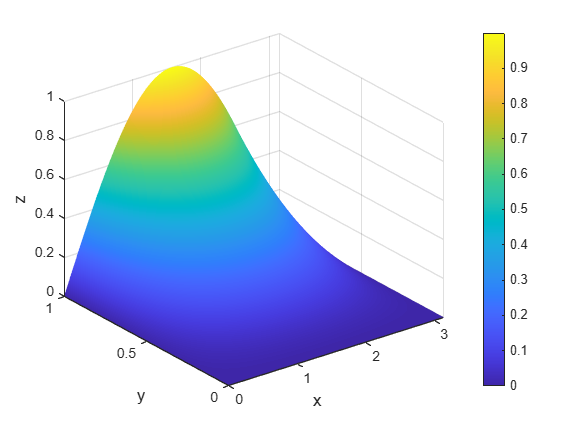

% Definisanje funkcije
fja = @(x, y) sin(x) .* y.^2;


x = linspace(0, pi, 100); 
y = linspace(0, 1, 100);  
% Pravljenje mreže
[X, Y] = meshgrid(x, y);  
Z = fja(X, Y);            

% Crtanje 3D grafika
figure;
surf(X, Y, Z, 'EdgeColor', 'none'); % Površinski grafikon
colorbar; % Bočna traka sa bojama


xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
zlabel('z', 'FontSize', 12);

grid on;
shading interp; % Interpolacija za bolji prikaz

#### Zadatak 2. - Trojni integral i numeričko rešenje pomoću integral3

Naći rešenje trojnog integrala:


$$I = \int_{0}^{2\pi} dx  \int_{0}^{1}\, y^2 \, dy  \int_{0}^{1} \, dz$$


Definišemo simbole i funkciju:

syms f(x, y, z);
f(x, y, z) = y^2

$$f(x, y, z) = y^{2}$$

Integralimo i dobijamo rešenje:

F = int(int(int(f, x, 0, 2*pi), y, 0, 1), z, 0, 1)

$$F = \frac{2\,\pi }{3}$$

eval(F)

ans = 2.0944

Sada ćemo koristiti proceduru ***integral3*** kako bismo **numerički** rešili ovaj integral.

clearvars
f = @(x, y, z)y.^2;
F = integral3(f, 0, 2*pi, 0, 1, 0, 1)

F = 2.0944

Grafik:

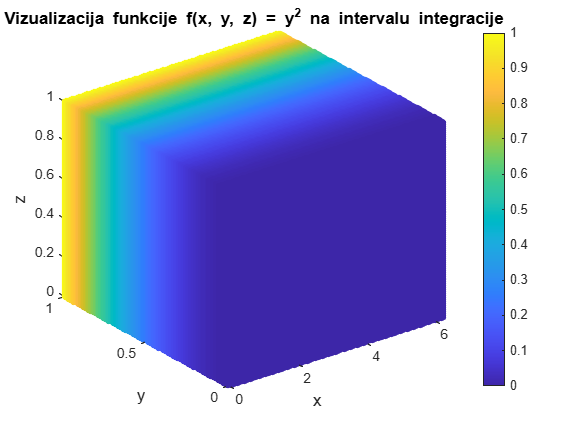

% Definišemo funkciju iz integrala: 1 * y^2 * 1 = y^2
f_3d = @(x, y, z) y.^2;

% Oblasti za x, y, z
x = linspace(0, 2 * pi, 100);
y = linspace(0, 1, 100);
z = linspace(0, 1, 100);

%Kreairanje i evaulacija mreže
[X, Y, Z] = meshgrid(x, y, z); 
F = f_3d(X, Y, Z); 

% Vizualizacija funkcije u 3D prostoru
figure;
scatter3(X(:), Y(:), Z(:), 15, F(:), 'filled'); % 3D tačkasti grafikon

colorbar; % Bočna traka sa bojama

% Postavljanje naslova i oznaka
title('Vizualizacija funkcije f(x, y, z) = y^2 na intervalu integracije', 'FontSize', 12);
xlabel('x', 'FontSize', 12);
ylabel('y', 'FontSize', 12);
zlabel('z', 'FontSize', 12);

grid on;
axis tight;

#### Zadatak 3. - Dvojni integral sa parametrom

Naći rešenje dvojnog integrala:


$$I = \int_{x=0}^{\pi}\int_{y=cos(a)}^{e^{-a}}{xsiny}\,dx \,dy$$


Rešava se standradno:

syms x y a;
f = x*sin(y)

$$f = x\,\sin\left(y\right)$$

F = int(int(f, x, 0, pi), y, cos(a), exp(-a))

$$F = \frac{\pi^{2}\,\left(\cos\left(\cos\left(a\right)\right)-\cos\left({\mathrm{e}}^{-a}\right)\right)}{2}$$

## Literatura

1. Nataša Ćirović, Numerička matematika, Beograd, 2018.

2. [Matlab Dokumentacija](https://www.mathworks.com/products/matlab.html), pristupljeno novembra 2024.

3. [Materijali sa Matematike 2 - Teams platforma](https://teams.microsoft.com/l/team/19%3aDjLrqQwsTgXsR3C_O6krlv59mS4kiaRPZzxbIUSNTIo1%40thread.tacv2/conversations?groupId=0e44125a-5fa8-4631-8d14-b1ddcf5e2a1b&tenantId=1774ef2e-9c62-478a-8d3a-fd2a495547ba), pristupljeno novembra 2024.

4. [Materijali sa Matematike 3](http://matematika3.etf.rs/testovi/testovi%20M3.pdf), pristupljeno novembra 2024.